# Analiza częstotliwościowa sygnału ADSL

%IMPORTFILE(FILETOREAD1)
%  Imports data from the specified file
%  FILETOREAD1:  file to read

%  Auto-generated by MATLAB on 26-Mar-2020 15:52:03

% Import the file
newData1 = load('-mat', 'lab_03.mat');

% Create new variables in the base workspace from those fields.
vars = fieldnames(newData1);
for i = 1:length(vars)
    assignin('base', vars{i}, newData1.(vars{i}));
end

% x_??:
mod(290916,16)+1 % ans = 5;

ans = 5


my_x = x_5;

% signal to matrix:

K = 8; N = 512; M = 32;

xMatr = zeros(K, N);

for i=0:K-1
    xMatr(i+1,:) = my_x(i*(N+M)+1+M:i*(N+M)+(N+M));
end

% XMatr = 

for i = 1:K
    XMatr(i,:) = fft(xMatr(i,:))./N;
end


% plots 

% fx1 = 1000*(0:N-1)/N;

fs=1000

fs = 1000

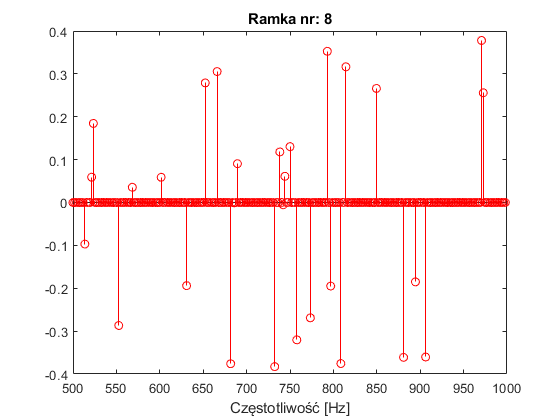

for m=1:K
    clf
    stem((0:N-1)*fs/(size(XMatr,2)) ...
        ,real(XMatr(m,:)), 'r o')
    xlabel('Częstotliwość [Hz]');
    xlim([500 1000])
    title("Ramka nr: " + m);
    pause(0.5);
end